# MODELO DE DIAGNÓSTICO

T=readtable('tablaFusionadaOrdenada.csv')

T = 1379×14 table
               image                Glaucoma       Area       Entropia_CR    Entropia_CV    Entropia_CA    mean_A    std_A     mean_H    std_H     mean_D     std_D     mean_V    std_V 
    ____________________________    ________    __________    ___________    ___________    ___________    ______    ______    ______    ______    _______    ______    ______    ______

    {'image_0001.jpg_1_1.jpg'  }       0        1.8224e+05      3.5854         6.2108          4.642       1001.7    756.34    3.8748  

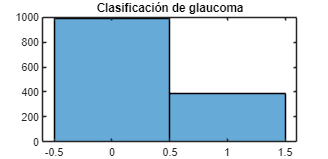


figure('Position', [0 0 350 170]);
histogram(T.Glaucoma)
title('Clasificación de glaucoma')

T.Glaucoma = cellstr(num2str(T.Glaucoma));

% Convert the values in the 'Glaucoma' column
for i = 1:height(T)
    if T.Glaucoma{i} == '1'
        T.Glaucoma{i} = 'Glaucoma';
    elseif T.Glaucoma{i} == '0'
        T.Glaucoma{i} = 'No Glaucoma';
    end
end



## Entrenamiento de modelo-KNN

### División de data

p = 0.2;
cv_out = cvpartition(T.Glaucoma, 'HoldOut', p, 'Stratify', true);
T_train = T(cv_out.training, :);
T_test  = T(cv_out.test, :);

k = 10;
cv_in = cvpartition(T_train.Glaucoma, 'KFold', k, 'Stratify', true);
% 
% Create cross-validated KNN model
mdl_knn = fitcknn(T_train, 'Glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_knn); % This row will print the mean error value. 

Error using classreg.learning.partition.PartitionedModel/checkFoldArgs
Indices of folds must be a vector with numbers between 1 and 0.

Error in classreg.learning.partition.ClassificationPartitionedModel/kfoldLoss (line 323)
            [mode,folds,extraArgs] = checkFoldArgs(this,varargin{:});

Estimate test performance

% Y_pred = kfoldPredict(mdl_knn); accuracy = sum(strcmp(Y_pred,
% T_train.Glaucoma)) / height(T_train);
results = table;
% results = [results; table("Knn", mdl_loss, accuracy,
% 'VariableNames',{'model','loss','accuracy'})];
% 
% figure('Position', [0 0 450 200]); confusionchart(T_train.Glaucoma,
% Y_pred, 'RowSummary','row-normalized') title('KNN confussion matrix');

## Entrenamiento de modelo-Tree


mdl_tree = fitctree(T_train, 'Glaucoma', 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(Y_pred,T_train.Glaucoma)) / height(T_train);
results = [results; table("Tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.Glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Tree confussion matrix');


## Entrenamiento de modelo-Naive Bayes

mdl_NB = fitcnb(T_train, 'Glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);
Y_pred = kfoldPredict(mdl_NB);
accuracy = sum(strcmp(Y_pred, T_train.Glaucoma)) / height(T_train);
results = [results; table("Naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];
figure('Position', [0 0 450 200]);
confusionchart(T_train.Glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Naive Bayes confussion matrix');


## Entrenamiento de modelo-Discriminant Analysis

% mdl_lda = fitcdiscr(T_train, 'Glaucoma','CVPartition', cv_in);
% mdl_loss = kfoldLoss(mdl_lda);
% Y_pred = kfoldPredict(mdl_lda);
% accuracy = sum(strcmp(Y_pred, T_train.Glaucoma)) / height(T_train);
% results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];
% 
% figure('Position', [0 0 450 200]);
% confusionchart(T_train.Glaucoma, Y_pred, 'RowSummary','row-normalized')
% title('LDA confussion matrix');

- To be different: Quadratic Discriminant Analysis (QDA)

% mdl_qda = fitcdiscr(T_train, 'Glaucoma','DiscrimType','quadratic','CVPartition',cv_in);
% mdl_loss = kfoldLoss(mdl_qda);
% Y_pred = kfoldPredict(mdl_qda);
% accuracy = sum(strcmp(Y_pred, T_train.Glaucoma)) / height(T_train);
% results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];
% 
% figure('Position', [0 0 450 200]);
% confusionchart(T_train.Glaucoma, Y_pred, 'RowSummary','row-normalized')
% title('QDA confussion matrix');


## Entrenamiento de modelo-SVM

mdl_svm = fitcsvm(T_train, 'Glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);
Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.Glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

results

[~, best_model] = max(results.accuracy);
results(best_model, :)

figure('Position', [0 0 450 200]);
confusionchart(T_train.Glaucoma, Y_pred, 'RowSummary','row-normalized')
title('SVM confussion matrix');

## Final model testing

mdl_final = fitcecoc(T_train, 'Glaucoma');
Y_pred = predict(mdl_final, T_test);

loss_final = loss(mdl_final, T_test)
accuracy_final = sum(strcmp(Y_pred, T_test.Glaucoma)) / height(T_test.Glaucoma)


figure('Position', [0 0 450 200]);
confusionchart(T_test.Glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Test confussion matrix');